# Examen RA3L "intro Matlab"       20 août 2025  13h30 -> 15h00 (1h30) 

% Nom :     ADDA                                       /8
% Prénom :    SAB  
% Matricule :   

## Identification d'un système : Décharge d'un Circuit RC

Le fichier "Step_Missing_Data.mat" contient la courbe de décharge d'un circuit RC. On souhaite utiliser ces données pour estimer l'impact de l'incertitude du condensateur sur la constante de temps du circuit. 

Seulement, problème : une partie des données de mesure sont corrompues (nan) !

Vous devez donc....

## **Exercice 1 : ( /1 point)**

Extraire les données du fichier Step_MissingData.mat" et les afficher sur un graphique

Ce fichier contient le vecteur x (le temps, en s) et yp (la tension, en volt)

Résultat attendu :

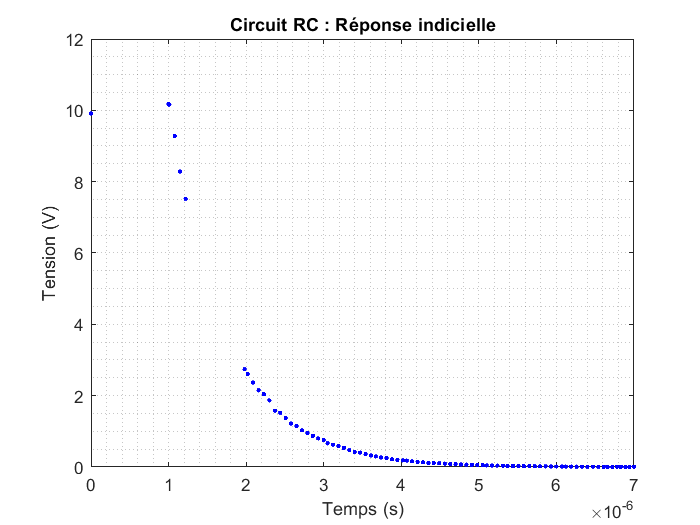

%code
clf;
clear all;
close all;
load('step_missing_data.mat');


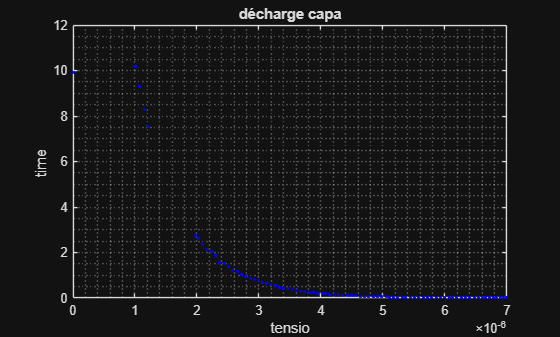

plot(x,yp,'.b')
grid minor
title('décharge capa')
xlabel('tensio')
ylabel('time ')

## **Exercice 2 : ( /2.5 points)**

Pour avancer vers notre but final, il nous faut dans un premier temps reconstruire le segment manquant... On souhaite donc réaliser une interpolation avec la méthode "Spline" sur la pente décroissante.

Pour ce faire, il faut : 

2.1 Garder uniquement les points dans la partie décroissate de la courbe de yp

2.2 Supprimer les données "NaN" du vecteur yp qui empêchent l'interpolation et stocker le résultat dans yp_cut

2.3 Créer un vecteur xnew qui reprend les abscisses des valeurs NaN 

2.4 Interpoler le vecteur résultant et stocker le resultat dans ynew

2.5 Créer un vecteur yinterp qui est le résultat de la concaténation de yp_cut et de ynew

Résultat attendu :

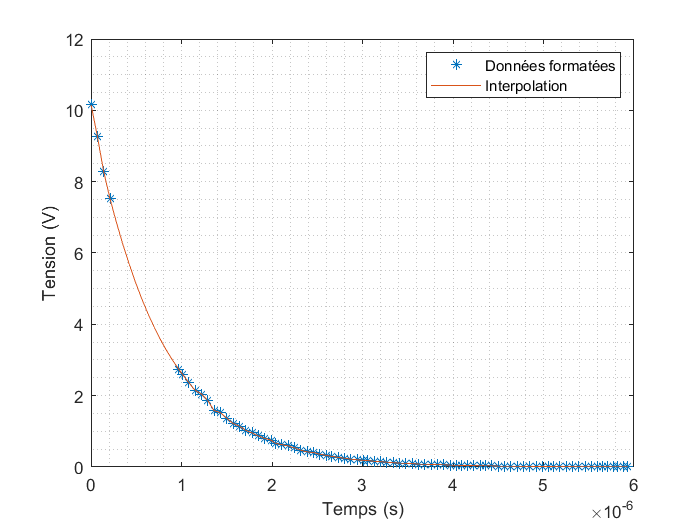

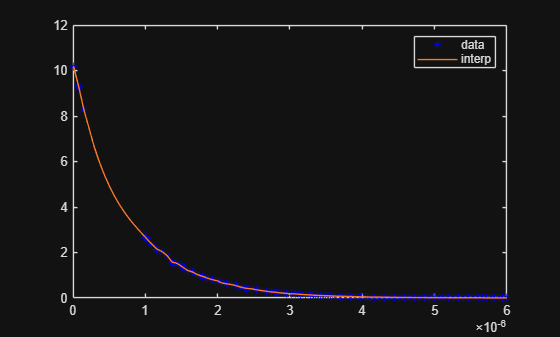

%code
clf;
%prendre partie decroissante 
be2=(find(diff(yp)<0)); 
be2 = [be2 be2(end)+1];%recupere dernier point
yp1=yp(be2);
x1=x(be2);

%x1=x1-x1(1);
%trouver les nan
oke=isnan(yp);

na1=find(oke,1,'first');
na2=find(oke,1,'last');

mank=x(na1:na2); %x des nan mais centré en 0
%mank= mank;
int=interp1(x1,yp1,mank,'spline');%interp des points manquants
%je mets tous les points ensemble pour la courbe complete et je mets dans
%le meme ordre
x3=[x1 mank];
[x3,ord]=sort(x3);
yp2=[yp1 int];
yp2=yp2(ord);

%recentrer sur 0 l'axe X
x1=x1-x1(1);
x3=x3-x3(1);

plot(x1,yp1,'*b',x3,yp2)
legend('data','interp')
hold on

## **Exercice 3 : ( /2 points)**

La valeur de la résistance est de 1 ohm. Celle du condensateur est en revanche inconnue... 

Sachant que l'équation de décharge d'un condensateur est $u\left(t\right)=U*\exp \left(-t/\textrm{RC}\right)$: 

3.1 Créer une fonction anonymous qui contient l'équation de la courbe de décharge d'un condensateur

3.2 Fitter au sens des moindre carré la fonction avec les données expérimentales contenus dans yp_cut en ajustant les paramètres U et C sachant que R = 1000 ohm

3.3 Afficher la courbe ajustée sur le graphe précédent et adapter la légende

Résultat attendu :

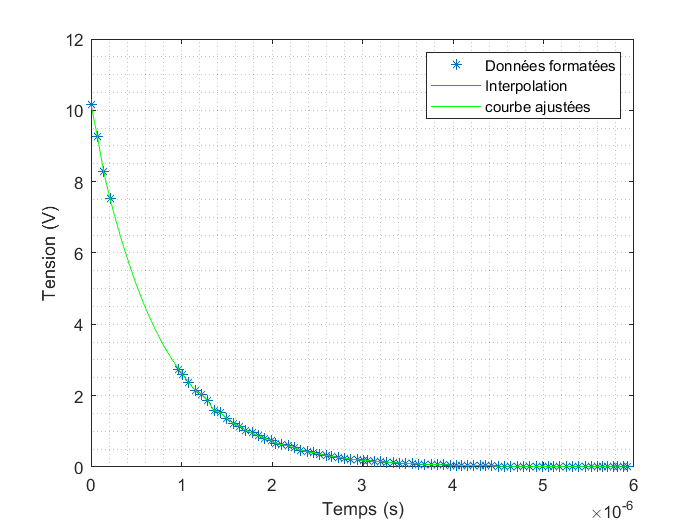

%code
format shortE

%clf;
R=1000;
P0=[5 1e-12]; % U et C
fun1=@(p,t) p(1).*exp(-t./(R.*p(2)));
cost1=@(izane) norm(yp1-fun1(izane,x1));

min1=fminsearch(cost1,P0)

min1 =    1.0228e+01   7.5120e-10


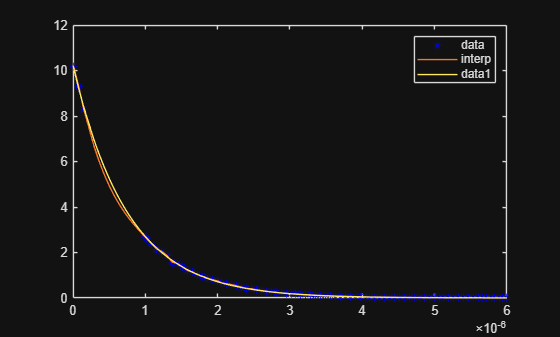

plot(x3,fun1(min1,x3))

## **Exercice 4 : ( /2.5 points)**

Nous avons maintenant la valeur du condensateur, nous pouvons donc désormais calculer la constante de temps Tau=R*C et l'effet d'une incertitude de +/-20% sur celle-ci. 

Pour cela, il faut : 

4.1 Réaliser une boucle permettant le calcul de la courbe de décharge pour une incertitude sur la valeur de capacité de -20% à +20% par pas de 20% (donc C-20%, C et C+20%)

4.2 Dans la même boucle, calculer le Tau correspondant à chaque valeur de C et afficher le résultat sur le graphique comme ci-dessous

Résultat attendu :

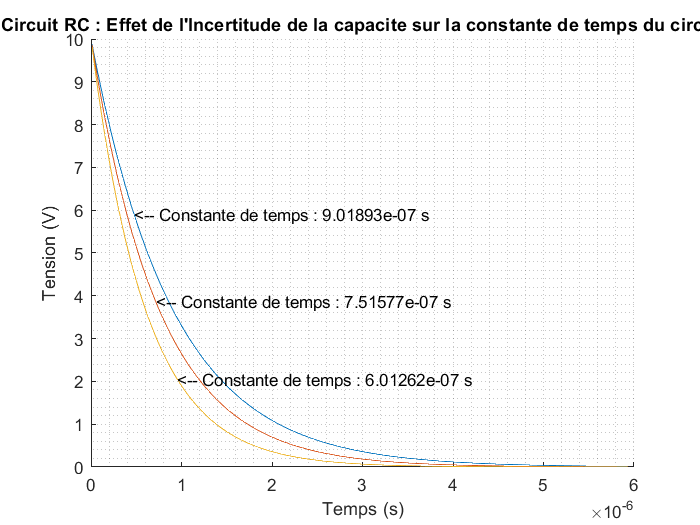

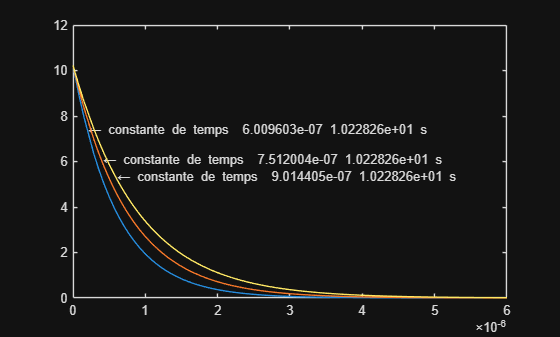

oke = '\leftarrow constante de temps  6.009603e-07 1.022826e+01 s'

oke = '\leftarrow constante de temps  7.512004e-07 1.022826e+01 s'

oke = '\leftarrow constante de temps  9.014405e-07 1.022826e+01 s'

%code
%d=linspace(0,9e-6,100);
%fun2=@(c) min1(1).*exp(-d./(R.*c));
%c=min1(2);
%cl=c*0.8;
%ch=c*1.2;
%plot(d,fun2(cl),d,fun2(c),d,fun2(ch))
c=min1(2);
clf;
for i=1:3
    p=min1;
    p(2)=c.*((-2+i)*0.2+1) ;%je veux un calcul qui fait que quand i=1 ca me donne c*0,_ qd i=2 c*1 et qad i=3 ca ft 1,2*c=c+20%
    plot(x3,fun1(p,x3))
    hold on
    tau=R.*p(2);
    ok=0.2*i*1e-6;
    oke=sprintf('\\leftarrow constante de temps  %6e s',tau)
    text(ok,fun1(p,ok),oke)
    hold on
end

© AIF MOL L2E